%load("testcl03_1.mat","Cm12","Cm13","CmC","Crm","step")
%load("testcl03_Anly.mat","clm")
load('testcl07_1.mat','Cm12','Crm')

dx=0.000001;
x = 0:dx:0.001; 
%plot(x,C(1:end,1));
%hold on
%axis([0,0.0003,0.01085,0.01125]);
%title(sprintf("Time:%d",j))
% drawnow;
% hold off


 Here is an example of how the function step works:
 Consider a randomly generated stable Transfer Function Model:
 of the form G(s)=num(s)/den(s):


num =          0   -0.1022    0.0316    0.1934   -0.1795    0.1620


den =     1.0000    6.2190   50.6538  222.7866  359.5180  162.7478


Call step using the following command (see also, help step):
step(tf(num,den));


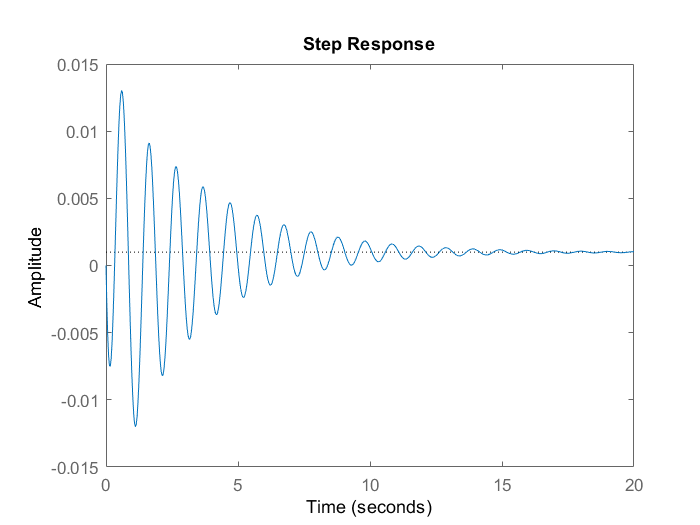

Output argument "yout" (and maybe others) not assigned during call to "step".

% Cm13=C(:,(step(1:27))-1);
% Cm12=C(:,(step(1:27))-1);
step=step./864000;

step1=step(1:10);

for y=1:100
    Cm12_1(:,y)=Cm12(y+3:899+y,y);
end

Index in position 2 exceeds array bounds (must not exceed 75).

x=0.000001:0.000001:0.000897

x = 	1.0e+-3 *

    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


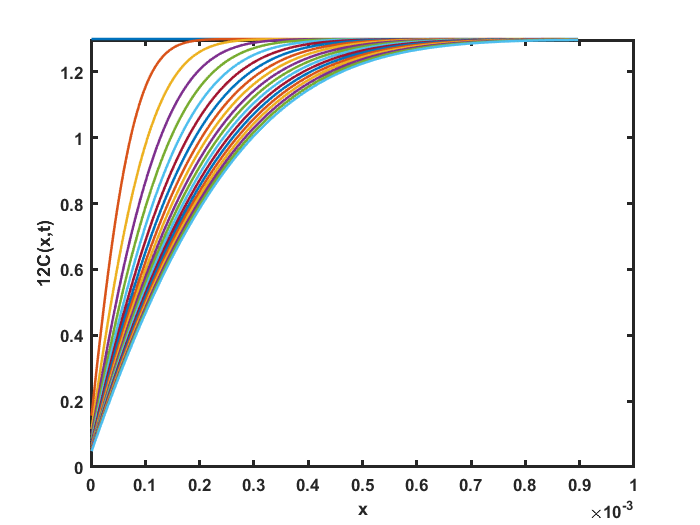

for r=1:5:500
plot(x,Cm12_1(:,r),"LineWidth",1.5); 
hold on
%plot([step(r) step(r)],[0 90],'--','color',[1 0 0])
axis([0,0.001,0,1.3]);
h=gca;
grid
%legendCell = cellstr(num2str(step1', '%2.3f days'));
%legend(legendCell);
h.YLimMode='manual';
h.FontSize=10;
h.FontWeight="bold";
h.LineWidth=1.8;
xlabel('x');
ylabel('12C(x,t)');
end
%print(gcf,'12C in different graphites.png','-dpng','-r320');
hold off

for r=1:15
plot(x,Cm13(:,r),"LineWidth",1.5);
hold on
%plot([step(r) step(r)],[0 1.1],'--','color',[1 0 0])
axis([0,0.00005,0,1.5]);
h=gca;
%legend;
grid
legendCell = cellstr(num2str(step1', '%2.3f days'));
legend(legendCell);
h.YLimMode='manual';
h.FontSize=10;
h.FontWeight="bold";
h.LineWidth=1.8;
xlabel('x');
ylabel('13c(x,t)');
end

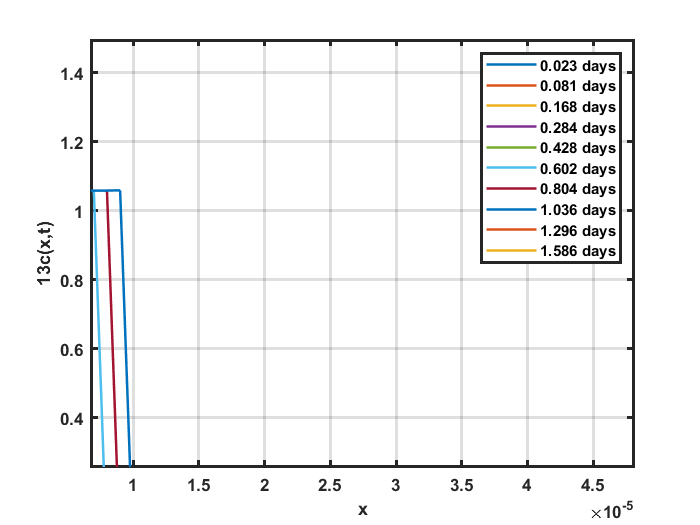

hold off

for r=1:15
plot(x,CmC(:,r),"LineWidth",1.1);
hold on
grid;
%plot([step(r) step(r)],[0.01085 0.01125],'--','color',[1 0 0])
axis([0,0.001,0.0111,0.01142]);
h=gca;
%legend;
legendCell = cellstr(num2str(step1', '%2.3f days'));
legend(legendCell);
h.YLimMode='manual';
h.FontSize=10;
h.FontWeight="bold";
h.LineWidth=1.8;
xlabel('x');
ylabel('\delta 13C');
end

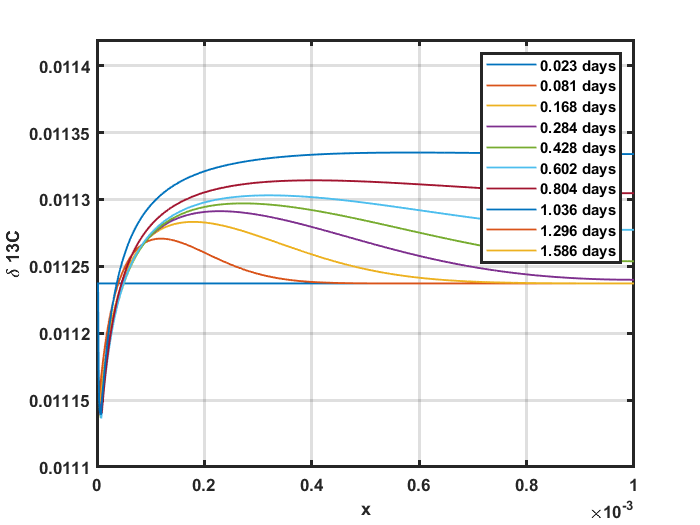

print(gcf,'delta13C in all.png','-dpng','-r320');
hold off

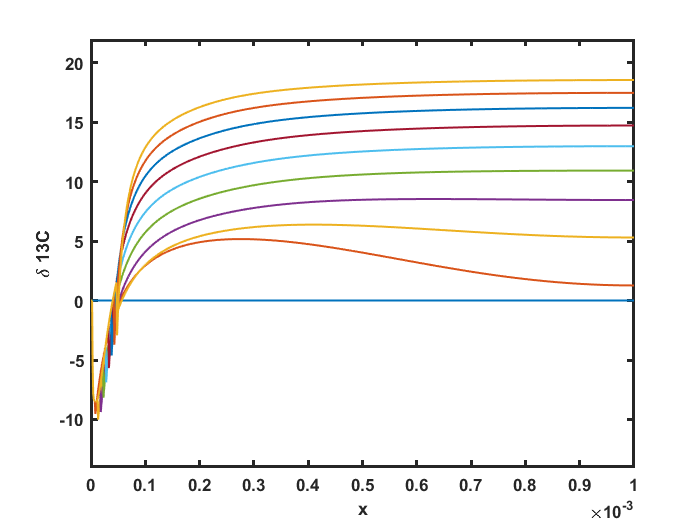

for r=1:5:50
plot(x,Crm(:,r),'LineWidth',1.2);
hold on
%plot([step(r) step(r)],[0.01085 0.01125],'--','color',[1 0 0])
%grid;
%plot([step(r) step(r)],[0.01085 0.01125],'--','color',[1 0 0])
axis([0.0,0.001,-14,22]);
h=gca;
%legend;
% legendCell = cellstr(num2str(step1', '%2.3f days'));
% legend(legendCell);
h.YLimMode='manual';
h.FontSize=10;
h.FontWeight="bold";
h.LineWidth=1.8;
xlabel('x');
ylabel('\delta 13C');
end
print(gcf,'delta13C in graphites.png','-dpng','-r320');
hold off

mymod=Crm(:,100)

Index in position 2 exceeds array bounds (must not exceed 75).